# 2015 Oct 07 PFISR (Long Pulse)

% Load Data
clear all
fileStr = 'C:\Users\Nithin\Documents\GitHub\Large Files\20151007.002_lp_1min-fitcal.h5';
beamCoordinates = h5read(fileStr,'/BeamCodes' );
time = h5read(fileStr,'/Time/UnixTime' );
timeMatlab = unix_to_matlab_time(double(time(1,:)));
altitude = h5read(fileStr,'/NeFromPower/Altitude' );
range = h5read(fileStr,'/NeFromPower/Range' );
Ne = h5read(fileStr,'/NeFromPower/Ne_NoTr' ); % Electron density in m^-3


## Calculate to Production Rate vs. Altitude

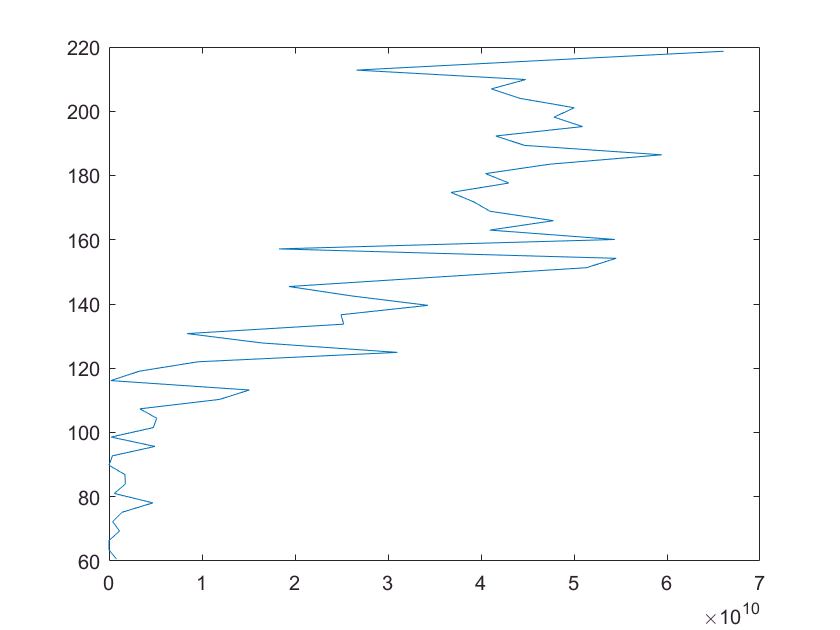

% Using Beam 13 (Magnetic Field Aligned)
altMax = 220; % km
altMin = 60; % km
timeMinStr = '7 Oct 2015 06:00';
timeMaxStr = '7 Oct 2015 07:00';
beamNo = 13;
altitude13=altitude(:,beamNo); % Unfortunately this starts from 123.5 km. 
altMaxNo = find_altitude(altitude13,altMax*1000);
altMinNo = find_altitude(altitude13,altMin*1000);
Ne(Ne<0)=0;
figure;
plot(Ne(altMinNo:1:altMaxNo,beamNo,2), altitude13(altMinNo:altMaxNo)/1000);

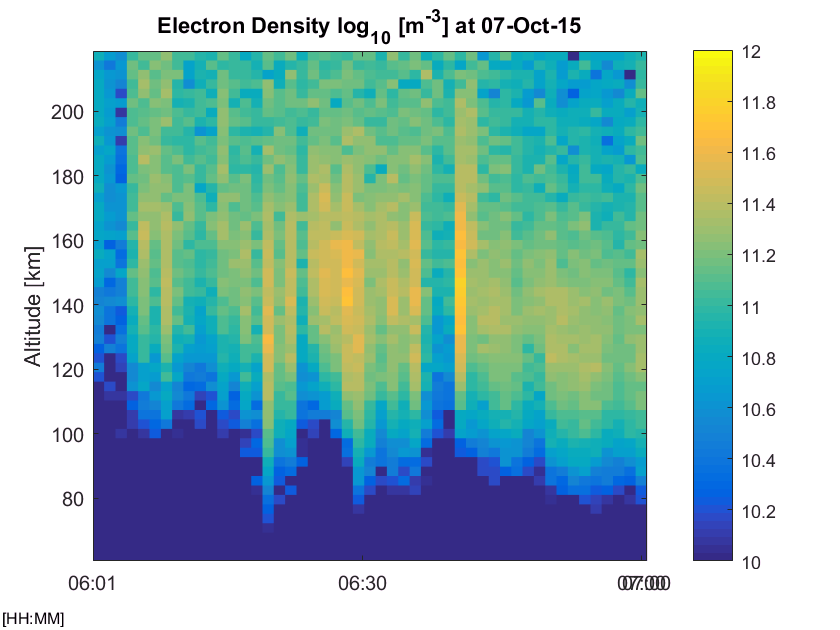

figure;
plot_2D_time_series(timeMatlab, altitude13(altMinNo:altMaxNo)/1000,log10(squeeze(Ne(altMinNo:altMaxNo,beamNo,:))),0.5,1, timeMinStr, timeMaxStr);
colorbar;
caxis([10, 12]);

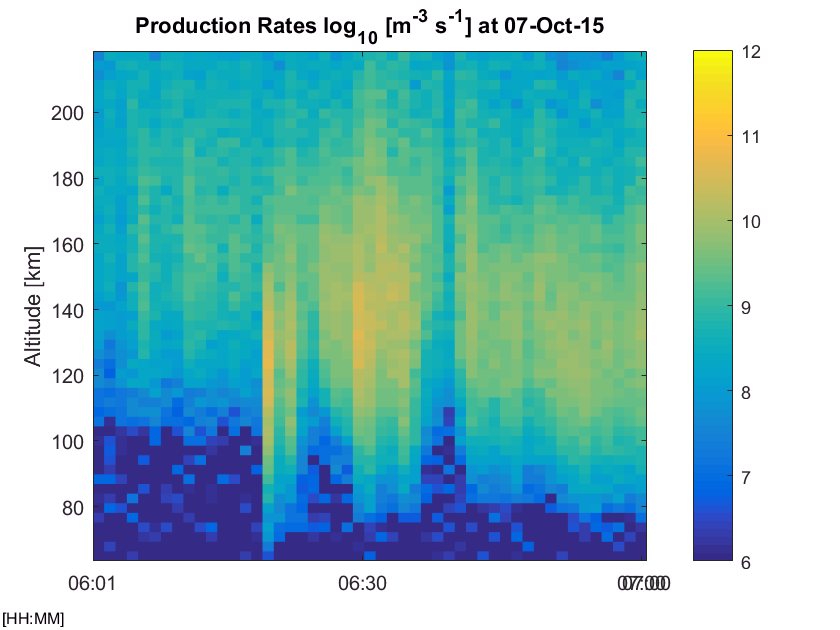

[NeCrop, timeCrop] = crop_time(squeeze(Ne(:,1,:)),timeMatlab,datenum(timeMinStr),datenum(timeMaxStr));
[NeCrop, altCrop] = crop_altitude(NeCrop,altitude13/1000,altMin, altMax); %km
[q, qTime, alpha] = get_production_rate(NeCrop,altCrop,timeCrop,2);
figure;
plot_2D_time_series(qTime, altCrop,log10(q),0.5,2, timeMinStr, timeMaxStr);
colorbar;
caxis([6, 12]);

## Calculate energy deposition matrix

energyBin=logspace(log10(500),6,25)';
A = get_energy_dep_matrix(altCrop,energyBin,65.126, -147.47, datenum(timeMinStr));

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In get_energy_dep_matrix (line 58)
  In 

## Calculate energy flux from production rate

data = get_inverted_flux(q, qTime, altCrop, energyBin, A);

2 %7.2104


4 %10.6056


6 %6.7245


8 %7.8147


10 %134.9697


12 %6.899


14 %8.1643


16 %7.4721


18 %17.5988


20 %25.3005


22 %8.57


24 %9.1259


26 %6.2777


28 %6.7498


30 %6.6034


32 %3.6787


34 %2.9887


36 %1.7973


38 %5.7173


40 %7.4907


42 %7.9531


44 %4.7466


46 %4.1929


48 %4.6119


50 %5.075


52 %5.7816


54 %6.5396


56 %3.6399


58 %4.3993


60 %8.0634


62 %6.8116


64 %5.0672


66 %8.127


68 %4.4079


70 %3.5057


72 %2.1818


74 %3.7567


76 %2.4884


78 %4.0658


80 %4.4644


82 %3.5384


84 %2.7754


86 %2.0775


88 %1.8268


90 %2.6946


92 %2.3386


94 %1.7916


96 %1.9181


98 %2.2846


100 %2.2035


## Plot energy flux

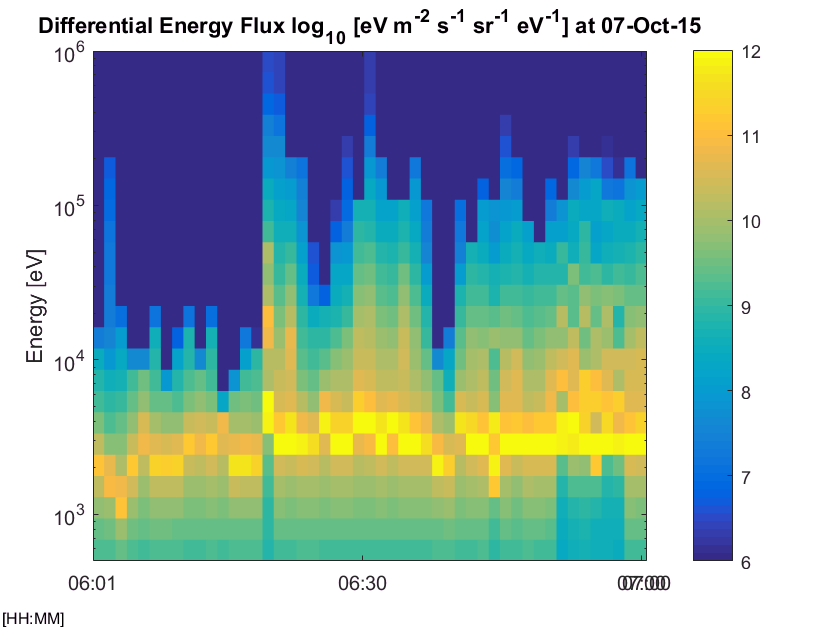

figure;
plot_2D_time_series(data.time, data.energyBin,real(log10(data.energyFlux)),0.5,3, timeMinStr, timeMaxStr);
colorbar;
caxis([6, 12]);